%% 含孔板缓冲罐的气流脉动计算
clc;
close all;
clear;
A=which('paperPlot_orificeOneVesselFreAndTrend_mlx.mlx');
index_ = strfind(A,'\');
index_ = index_(end);
currentPath = A(1:index_);

%含孔板缓冲罐的气流脉动计算
%   Detailed explanation goes here
%  L1  l    Lv1     Lv2   l  L2
%        __________________
%       |         |        |
% ------|     V1   d    V2 |-------
%       |_________|________|
%    Dpipe  Dv1    d   Dv2    Dpipe 

massFlow = load(fullfile(currentPath,'mass_flow_0.1478_NorthZone.txt'));
N = 4096;
time = massFlow(1:N,1);
massFlowRaw = massFlow(1:N,2);
Fs = 1/(time(2)-time(1));
[FreRaw,AmpRaw,PhRaw,massFlowE] = fun_fft(detrend(massFlowRaw),Fs);
% 提取主要频率
[pks,locs] = findpeaks(AmpRaw);
Fre = FreRaw(locs);
massFlowE = massFlowE(locs);
temp = Fre < 100;
%temp = (Fre<29) | (Fre>30 & Fre < 100);
Fre = Fre(Fre < 100);
massFlowE = massFlowE(temp);
isDamping = 1;
%绘图参数
isXLength = 1;
isShowStraightPipe=1;%是否显示直管
isShowOnlyVessel=1;%是否显示无内件缓冲罐
inputData = [...
    %1    2  3     4   5   6     7      8      9  
    %L1  ,L2,Dpipe,Dv1,Dv2,l    ,Lv1   ,Lv2   ,d
     2.94,10,0.106,0.45,0.45,0.115,0.4755,0.4755,0.106/2 ...
];

for i=1:size(inputData,1)
    xTick(i) = inputData(i,2);
    xTickLabel{i} = sprintf('间距%gm',inputData(i,2));
end

opt.frequency = 10;%脉动频率
opt.acousticVelocity = 345;%声速
opt.isDamping = isDamping;%是否计算阻尼
opt.coeffDamping = 0.1;%阻尼
opt.coeffFriction = 0.03;%管道摩察系数
opt.meanFlowVelocity = 14.6;%管道平均流速
opt.isUseStaightPipe = 0;%计算容器传递矩阵的方法
y1 = [0,1,2,2.7];
y2 = [3.5,4,5,6,7,8,8.7,9.7,10.7,11.7,12.7,12.94]

y2 =     3.5000    4.0000    5.0000    6.0000    7.0000    8.0000    8.7000    9.7000   10.7000   11.7000   12.7000   12.9400


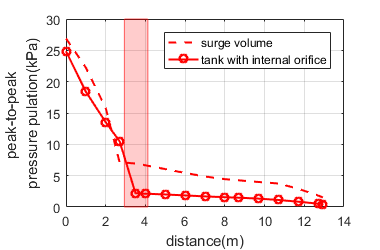


for i = 1:size(inputData,1)
    name{i} = sprintf('L1:%g,L2:%g',inputData(i,1),inputData(i,2));
    desp{i} = sprintf('L1:%g,L2:%g,d:%g,Dpipe:%g,Dv1:%g,Dv2:%g,l:%g,Lv1:%g,Lv2:%g'...
        ,inputData(i,1),inputData(i,2),inputData(i,9),inputData(i,3),inputData(i,4)...
        ,inputData(i,5),inputData(i,6),inputData(i,7),inputData(i,8));
    
    para(i).opt = opt;
    para(i).L1 = inputData(i,1);%L1(m)
    para(i).L2 = inputData(i,2);%缓冲罐中间连接管道的长度（m） 
    para(i).Dpipe = inputData(i,3);%管道直径（m）
    para(i).Dv1 = inputData(i,4);
    para(i).Dv2 = inputData(i,5);    
    para(i).l = inputData(i,6);%0.115;%缓冲罐前管道的长度(m)   
    para(i).Lv1 = inputData(i,7);%[[0.157,0.25,0.5,0.75],[1:0.25:5]];%第一个缓冲罐的直径（m）
    para(i).Lv2 = inputData(i,8);%0.5;%第二个缓冲罐的直径（m）
    para(i).d = inputData(i,9);%孔板直径

    para(i).sectionL1 = [0,1,2,2.7];%[0:1:para(i).L1,para(i).L1];
    para(i).sectionL2 = [3.5,4,5,6,7,8,8.7,9.7,10.7,11.7,12.7,12.94]- (para(i).L1+para(i).Lv1+para(i).Lv2+2*para(i).l);%0:1:para(i).L2;
end

dcpss = getDefaultCalcPulsSetStruct();
dcpss.calcSection = [0.5,0.6];
dcpss.fs = Fs;
dcpss.isHp = 0;
dcpss.f_pass = 7;%通过频率5Hz
dcpss.f_stop = 5;%截止频率3Hz
dcpss.rp = 0.1;%边带区衰减DB数设置
dcpss.rs = 30;%截止区衰减DB数设置
afterPressure = [];
for i = 1:length(para)
    pressure1 = [];
    pressure2 = [];

    [pressure1,pressure2] = ...
        vesselHaveOrificePulsationCalc(massFlowE,Fre,time,...
        para(i).L1,para(i).L2,...
        para(i).Lv1,para(i).Lv2,para(i).l,para(i).Dpipe,para(i).Dv1,para(i).Dv2,...
        para(i).d,...
        para(i).sectionL1,para(i).sectionL2,...
        'a',opt.acousticVelocity,'isDamping',opt.isDamping,'friction',opt.coeffFriction,...
        'meanFlowVelocity',opt.meanFlowVelocity);%,'coeffDamping',opt.coeffDamping
    pressure = [pressure1,pressure2];
    plus1{i} = calcPuls(pressure1,dcpss);
    plus2{i} = calcPuls(pressure2,dcpss);
    plus{i} = [plus1{i},plus2{i}];
    if i == 1
        [pressure1OV,pressure2OV] = oneVesselPulsationCalc(massFlowE,Fre,time,...
            para(i).L1,para(i).L2,...
            para(i).Lv1+para(i).Lv2,para(i).l,para(i).Dpipe,para(i).Dv1,...
            para(i).sectionL1,para(i).sectionL2,...
            'a',opt.acousticVelocity,'isDamping',opt.isDamping,'friction',opt.coeffFriction,...
            'meanFlowVelocity',opt.meanFlowVelocity);
        pressureOV = [pressure1OV,pressure2OV];
        plus1OV = calcPuls(pressure1OV,dcpss);
        plus2OV = calcPuls(pressure2OV,dcpss);
        plusOV = [plus1OV,plus2OV];
    end
    if isempty(plus1{i})
        maxPlus1(i) = nan;
    else
        maxPlus1(i) = max(plus1{i});
    end

    if isempty(plus2{i})
        maxPlus2(i) = nan;
    else
        maxPlus2(i) = max(plus2{i});
    end

    
    newSectionL2 = para(i).L1 + 2*para(i).l+para(i).Lv1 + para(i).Lv2 + para(i).sectionL2;

    realLengthSection{i} = [para(i).sectionL1,newSectionL2];

    L_straight(i) = para(i).L1 + para(i).L2 + para(i).Lv1 + para(i).Lv2 + 2*para(i).l;
    temp = find(realLengthSection{i}>para(i).L1);
    sepratorIndex(i) = temp(1);
    %temp = fun_straightPipe(massFlowE1,L_straight(i),para(i).Dpipe,para(i).opt,realLengthSection{i});
    temp = straightPipePulsationCalc(massFlowE,Fre,time,L_straight(i),realLengthSection{i}...
	,'d',para(i).Dpipe,'a',opt.acousticVelocity,'isDamping',opt.isDamping,'friction',opt.coeffFriction,'meanFlowVelocity',opt.meanFlowVelocity);
    temp = calcPuls(temp,dcpss);
    maxPlus1Straight(i) = max(temp(1:sepratorIndex(i)));
    maxPlus3Straight(i) = max(temp(sepratorIndex(i):end));
    plusStraight{i} = temp;
    temp2 = plus{i};
    temp(temp<1e-4) = 1;
    temp2(temp2<1e-4) = 1;
    reduceRate{i} = (temp - temp2)./temp;
    
    maxPlus1Straight(i) = max(temp(1:sepratorIndex(i)));
    maxPlus3Straight(i) = max(temp(sepratorIndex(i):end));

end

%% 绘图 - 绘制孔板-直管-缓冲罐随测点布置的趋势图
if 1
    isShowStraightPipe = 0;
    figure
    h = [];
    textLegend = {};
    hold on;
    plotCount = 1;
    for i = 1:length(para)

        Y = plus{i};
        Y = Y./1000;
        Y=Y';
        if isXLength
            X = realLengthSection{i};
        else
            X = 1:length(Y);
        end
        if isShowStraightPipe
            h(plotCount) = plot(X,plusStraight{i}./1000,':r','LineWidth',1.5);
            textLegend{plotCount} = 'pipe without suppressors';
            plotCount = plotCount + 1;
        end
        if isShowOnlyVessel
            h(plotCount) = plot(X,plusOV./1000,'--r','LineWidth',1.5);
            textLegend{plotCount} = 'surge volume';
            plotCount = plotCount + 1;
        end
        h(plotCount) = plot(X,Y,'-or','LineWidth',1.5);
        textLegend{plotCount} = 'tank with internal orifice';
        plotCount = plotCount + 1;
    end

    legend(h,textLegend,0);
    grid on;
    if isXLength
        xlabel('distance(m)');
    else
        xlabel('distance(m)');
    end
    ylabel(sprintf('peak-to-peak \npressure pulation(kPa)'));
    set(gcf,'color','w');
    set(gcf,'position',[200,200,380,250]);
    x1 = inputData(1,1);
    x2 = x1 + inputData(1,6)*2+inputData(1,7)+inputData(1,8);
    ax = axis();
    h = fill([x1,x2,x2,x1,x1],[ax(3),ax(3),ax(4),ax(4),ax(3)],'r');
    set(h,'faceAlpha',0.2);
    set(h,'EdgeColor','r');
    set(h,'EdgeAlpha',0.6);
    box on;
%export_fig(gcf,'d:\cloudDisk\share\【论文】孔板\图\直管-缓冲罐-内件缓冲罐对比.png','-m3.5','-painters')
end 

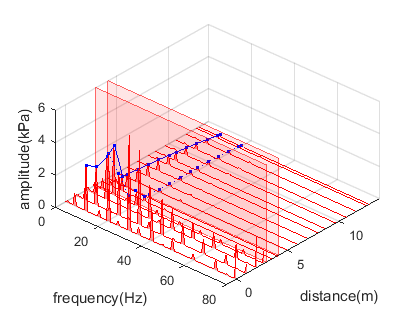

%% 0.5D孔板缓冲罐罐后管道-频谱瀑布图
if 0
    y=newSectionL2;
    %计算每个通道的频谱
    figure
    hold on;
    AmpRecorder = [];
    for i=1:size(pressure2,2)
        [fre,amp]=fun_fft(detrend(pressure2(:,i)./1000),Fs);
        indexBeDelete = find(fre>80);
        fre(indexBeDelete) = [];
        amp(indexBeDelete) = [];
        plotSpectrum3(fre,amp,y(i),'isFill',1);
        AmpRecorder(:,i) = amp;
    end 
    indexBeFind = find(fre>9.5 & fre < 10.5);
    maxAmp = [];
    for i = 1:size(AmpRecorder,2)
        maxAmp(i)=max(AmpRecorder(indexBeFind,i));
    end 
    plot3(ones(1,size(AmpRecorder,2)).*10,y,maxAmp,'.-b');
    grid on;
    ylim([y(1)-1,y(end)+1]);
    xlabel('frequency(Hz)');
    ylabel('distance(m)');
    zlabel('amplitude(kPa)');
    set(gcf,'color','w');
    view(-25,36);
end
%box on;

%% 0.5D孔板缓冲罐全通道频谱瀑布图
if 1
    y=realLengthSection{1};
    %计算每个通道的频谱
    figure
    hold on;
    AmpRecorder = [];
    for i=1:size(pressure,2)
        [fre,amp]=fun_fft(detrend(pressure(:,i)./1000),Fs);
        indexBeDelete = find(fre>80);
        fre(indexBeDelete) = [];
        amp(indexBeDelete) = [];
        plotSpectrum3(fre,amp,y(i),'isFill',1);
        AmpRecorder(:,i) = amp;
    end 
    %绘制10Hz主频率
    indexBeFind = find(fre>9.5 & fre < 10.5);
    maxAmp = [];
    for i = 1:size(AmpRecorder,2)
        maxAmp(i)=max(AmpRecorder(indexBeFind,i));
    end 
    plot3(ones(1,size(AmpRecorder,2)).*10,y,maxAmp,'.-b');
    %绘制20Hz主频率
    indexBeFind = find(fre>19.5 & fre <20.5);
    maxAmp = [];
    for i = 1:size(AmpRecorder,2)
        maxAmp(i)=max(AmpRecorder(indexBeFind,i));
    end 
    plot3(ones(1,size(AmpRecorder,2)).*20,y,maxAmp,'.:b');

    grid on;
    view(51,44);
    ax = axis();
    y1 = inputData(1,1);
    y2 = x1 + inputData(1,6)*2+inputData(1,7)+inputData(1,8);
    fh = fill3([ax(1),ax(2),ax(2),ax(1),ax(1)],ones(1,5).*y1,[ax(5),ax(5),ax(6),ax(6),ax(5)],'r');
    set(fh,'FaceAlpha',0.1);
    set(fh,'EdgeColor','r','EdgeAlpha',0.6);
    fh = fill3([ax(1),ax(2),ax(2),ax(1),ax(1)],ones(1,5).*y2,[ax(5),ax(5),ax(6),ax(6),ax(5)],'r');
    set(fh,'FaceAlpha',0.1);
    set(fh,'EdgeColor','r','EdgeAlpha',0.6);

    ylim([y(1)-1,y(end)+1]);
    xlabel('frequency(Hz)');
    ylabel('distance(m)');
    zlabel('amplitude(kPa)');
    set(gcf,'color','w');
    %box on;
    %export_fig(gcf,'d:\cloudDisk\share\【论文】孔板\图\0.5D孔板全段频谱瀑布图.png','-m3.5','-painters','-transparent')
    view(42,50);
    set(gcf,'position',[200,200,420,320]);
end

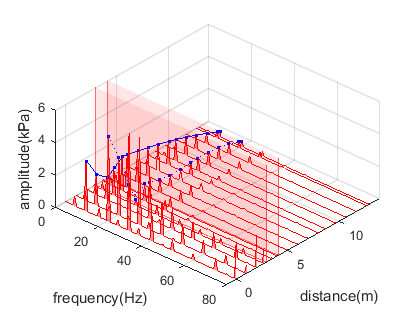


%% 单一缓冲罐全通道频谱瀑布图
if 1
    y=realLengthSection{1};
    %计算每个通道的频谱
    figure
    hold on;
    AmpRecorder = [];
    for i=1:size(pressureOV,2)
        [fre,amp]=fun_fft(detrend(pressureOV(:,i)./1000),Fs);
        indexBeDelete = find(fre>80);
        fre(indexBeDelete) = [];
        amp(indexBeDelete) = [];
        plotSpectrum3(fre,amp,y(i),'isFill',1);
        AmpRecorder(:,i) = amp;
    end 
    %绘制10Hz主频率
    indexBeFind = find(fre>9.5 & fre < 10.5);
    maxAmp = [];
    for i = 1:size(AmpRecorder,2)
        maxAmp(i)=max(AmpRecorder(indexBeFind,i));
    end 
    plot3(ones(1,size(AmpRecorder,2)).*10,y,maxAmp,'.-b');
    %绘制20Hz主频率
    indexBeFind = find(fre>19.5 & fre <20.5);
    maxAmp = [];
    for i = 1:size(AmpRecorder,2)
        maxAmp(i)=max(AmpRecorder(indexBeFind,i));
    end 
    plot3(ones(1,size(AmpRecorder,2)).*20,y,maxAmp,'.:b');

    grid on;
    view(51,44);
    ax = axis();
    y1 = inputData(1,1);
    y2 = x1 + inputData(1,6)*2+inputData(1,7)+inputData(1,8);
    fh = fill3([ax(1),ax(2),ax(2),ax(1),ax(1)],ones(1,5).*y1,[ax(5),ax(5),ax(6),ax(6),ax(5)],'r');
    set(fh,'FaceAlpha',0.1);
    set(fh,'EdgeColor','r','EdgeAlpha',0.6);
    fh = fill3([ax(1),ax(2),ax(2),ax(1),ax(1)],ones(1,5).*y2,[ax(5),ax(5),ax(6),ax(6),ax(5)],'r');
    set(fh,'FaceAlpha',0.1);
    set(fh,'EdgeColor','r','EdgeAlpha',0.6);

    ylim([y(1)-1,y(end)+1]);
    zlim([0,6]);
    xlabel('frequency(Hz)');
    ylabel('distance(m)');
    zlabel('amplitude(kPa)');
    set(gcf,'color','w');
    %box on;
    %export_fig(gcf,'d:\cloudDisk\share\【论文】孔板\图\0.5D孔板全段频谱瀑布图.png','-m3.5','-painters','-transparent')
    view(42,50);
    set(gcf,'position',[200,200,420,320]);
end